# Fourier Series Properties

Fourier series expresses a periodic function, f(t), in terms of an infinite sum of sines and cosines. This examples demonstrates the properties of the Fourier series in a visual way. 

*Copyright © Angora Tutor, 2020. All rights reserved.*

## Introduction

Let's first remember the Fourier series analysis and synthesis formulas.For simplicity in notation, we will use complex coefficients. The analysis equation finds the Fourier coefficients of a periodic signal, $f\left(t\right)$, where $T$ is the period.


$$c_n =\frac{1}{T}\int_0^T f\left(t\right)e^{\left(\frac{-j2\pi \;t\;n}{T}\right)} \textrm{dt}$$


The synthesis equation reconstructs (synthesizes) the function using the Fourier coefficients.


$$f_s \left(t\right)=\sum_{n=-\infty }^{\infty } c_n e^{\left(\frac{j2\pi \;n\;t}{T}\right)}$$


We will use the following functions to demonstrate the Fourier analysis and synthesis properties. 

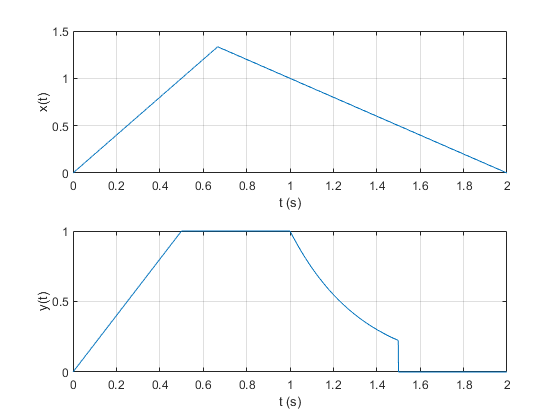

T = 2;
Ts = 1e-3;
[x,t] = xValues(T, Ts);

figure
subplot(2,1,1)
plot(t,x)
xlabel('t (s)')
ylabel('x(t)')
grid on

y = yValues(T, Ts);
subplot(2,1,2)
plot(t,y)
xlabel('t (s)')
ylabel('y(t)')
grid on

We will use N harmonics to plot. The following is the Fourier coefficients for these function.

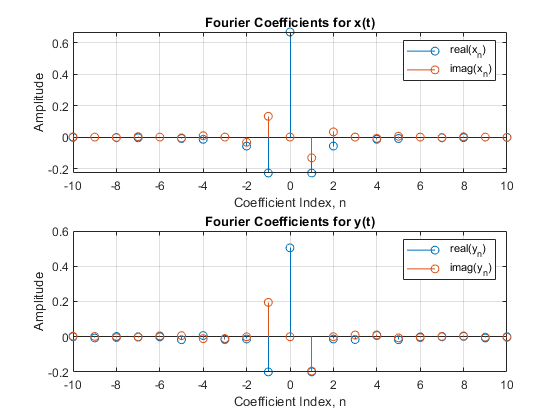

N = 10;
x_n = analysis(x,t,T,N,Ts);
y_n = analysis(y,t,T,N,Ts);

figure
subplot(2,1,1)
stem(-N:N, real(x_n))
hold on
stem(-N:N, imag(x_n))
hold off
grid on
legend('real(x_n)', 'imag(x_n)')
xlabel('Coefficient Index, n')
ylabel('Amplitude')
title('Fourier Coefficients for x(t)')

subplot(2,1,2)
stem(-N:N, real(y_n))
hold on
stem(-N:N, imag(y_n))
hold off
grid on
legend('real(y_n)', 'imag(y_n)')
xlabel('Coefficient Index, n')
ylabel('Amplitude')
title('Fourier Coefficients for y(t)')

## Linearity

Fourier series analysis is a linear operation. Assume that there are two function $x\left(t\right)$ and $y\left(t\right)$ with the same period, $T$, have Fourier coefficients $x_n$ and $y_n$, respectively. If there is a function $z\left(t\right)$, which is a linear combination of $x\left(t\right)$ and $y\left(t\right)$, such that 


$$z\left(t\right)=a\;x\left(t\right)+b\;y\left(t\right)$$
 

then the Fourier coefficients of $z\left(t\right)$ is also a linear combination of $x_n$ and $y_n$:


$$z_n ={a\;x}_n +{b\;y}_n$$


Let's first set $b$ to zero and see what happens when we scale the time domain function.

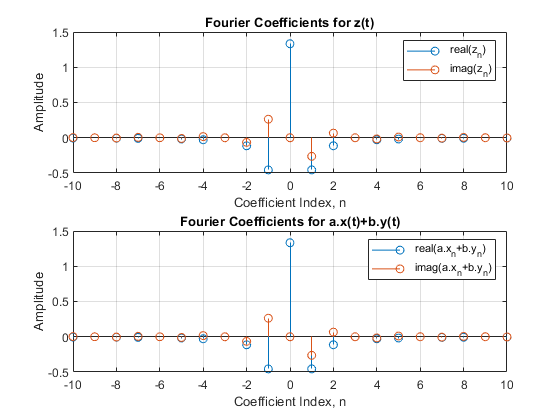

a = 2;
b = 0;
z_n = analysis(a*x+b*y,t,T,N,Ts);

plotFourierCoefficients(z_n,'z_n','z(t)',...
    a*x_n+b*y_n,'a.x_n+b.y_n','a.x(t)+b.y(t)')

Let's try with both functions.

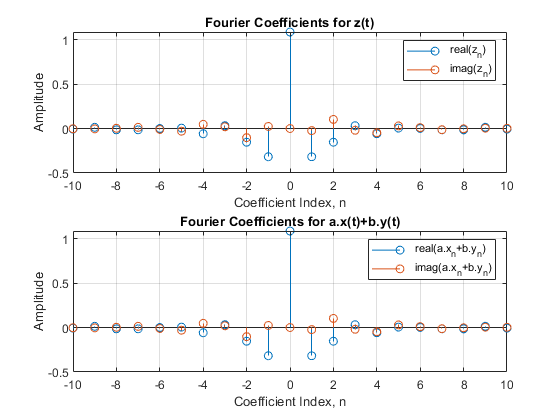

a = pi;
b = -2;
z_n = analysis(a*x+b*y,t,T,N,Ts);

plotFourierCoefficients(z_n,'z_n','z(t)',...
    a*x_n+b*y_n,'a.x_n+b.y_n','a.x(t)+b.y(t)')

How about complex weights?

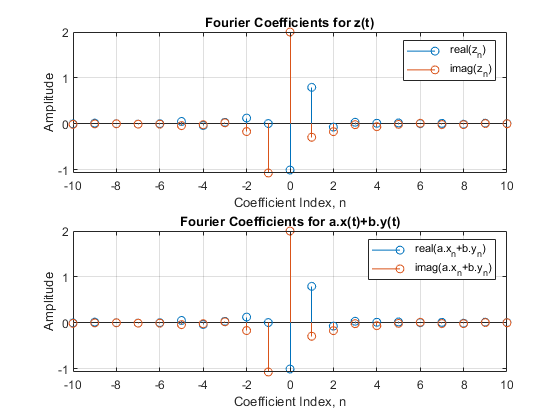

a = 3i;
b = -2;
z_n = analysis(a*x+b*y,t,T,N,Ts);

plotFourierCoefficients(z_n,'z_n','z(t)',...
    a*x_n+b*y_n,'a.x_n+b.y_n','a.x(t)+b.y(t)')

## Time Reversal

For a function $y\left(t\right)$ with Fourier coefficients $y_n$, the time reversed function $z\left(t\right)=y\left(-t\right)$ has the Fourier coefficients $z_n =y_{-n}$. To demosntrate this, we need a non-symmetric function, so we use $y\left(t\right)$. This property also points out that, even symmetric functions have even symmetric Fourier series.

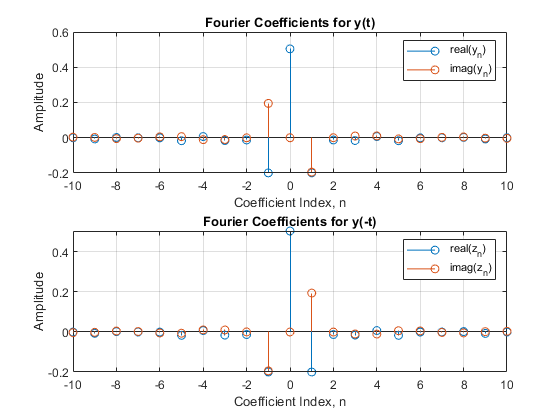

z_n = analysis(fliplr(y),t,T,N,Ts);

plotFourierCoefficients(y_n,'y_n','y(t)',...
    z_n,'z_n','y(-t)')

max(abs(z_n - fliplr(y_n)))

ans = 8.7622e-04

## Time Scaling

For a function $x\left(t\right)$ with Fourier coefficients $x_n$, consider the time scaled function $z\left(t\right)=x\left(a\;t\right)$. $x\left(t\right)$ has a period of $T$. 


$$\begin{array}{l}
x\left(t\right)=x\left(t+T\right)\\
x\left(a\;t\right)=x\left(a\;t+T\;\right)=x\left(a\left(t+\frac{T}{a}\right)\right)
\end{array}$$


$x\left(a\;t\right)=z\left(t\right)$ has a period of $\frac{T}{a}=T_z$. First plot $z\left(t\right)=x\left(a\;t\right)$, where $a$=4. 

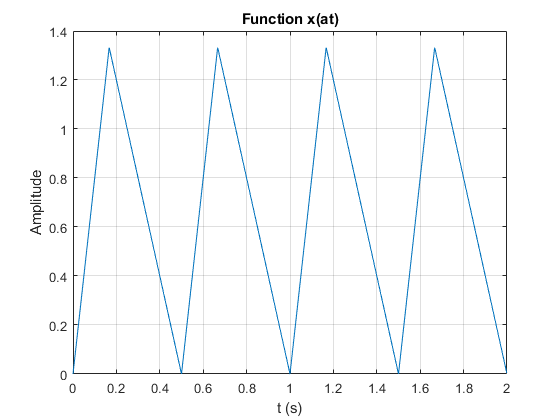

a = 4;
figure
t=0:Ts:T-Ts;
ax = xFun(a*t, T, Ts);
plot(t,ax)
grid on
xlabel('t (s)')
ylabel('Amplitude')
title('Function x(at)')


$$\begin{array}{l}
z_n =\frac{1}{T_z }\int_0^{T_z } z\left(t\right)e^{\left(\frac{-j2\pi \textrm{tn}}{T_z }\right)} \textrm{dt}\\
\;\;\;=\frac{1}{T_z }\int_0^{T_z } x\left(\textrm{at}\right)e^{\left(\frac{-j2\pi \textrm{tn}}{T_z }\right)} \textrm{dt}
\end{array}$$


Let $t\prime =a\;t$, substitute $t\;=\;t\prime /a\;$.


$$\begin{array}{l}
z_n =\frac{1}{aT_z }\int_0^{{\textrm{aT}}_z } x\left(t\prime \;\right)e^{\left(\frac{-j2\pi t\prime \;n}{{\textrm{aT}}_z }\right)} \textrm{dt}\prime \;\\
\;\;\;\;=\frac{1}{T}\int_0^T x\left(t\prime \;\right)e^{\left(\frac{-j2\pi t\prime \;n}{T}\right)} \textrm{dt}\prime \\
z_n =x_n 
\end{array}$$


So, the Fourier coefficients are exactly the same. So, what has changed when we scaled the time? Let' write the synthesis equation


$$\begin{array}{l}
z\left(t\right)=\sum_{n=-\infty }^{\infty } z_n e^{\left(\frac{j2\pi \;n\;t}{T_z }\right)} \\
\;\;\;\;\;\;\;=\sum_{n=-\infty }^{\infty } z_n e^{\left(\frac{j2\pi \;a\;n\;t}{T}\right)} \\
\;\;\;\;\;\;\;=\sum_{n=-\infty }^{\infty } z_n e^{\left({j\;a\;w}_n \;t\right)} 
\end{array}$$


If we write the harmonic frequencies for the original signal, $x\left(t\right)$, as $w_n =2\pi n\;f_0$, where $\;f_0 =\frac{1}{T}$, then the harmonic frequencies for $x\left(a\;t\right)$ is ${w\prime \;}_n =2\pi n\;{a\;f}_0 =a\;w_n$.

So, the difference is, the coefficients are for a new set of frequencies. 

Let's see this in action. Get one period of $z\left(t\right)\;=\;x\left(a\;t\right)$ and caculate the Fourier coefficients. Don't forget to set the perios to $T_z =\frac{T}{a}$.

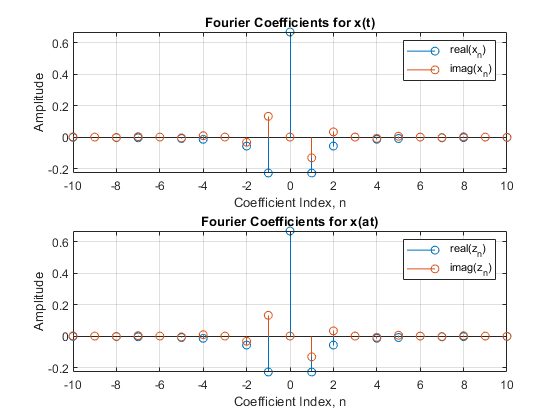

Tz = T/a;
z = ax(t<(Tz));
z_n = analysis(z,t(t<(T/a)),T/a,N,Ts);

plotFourierCoefficients(x_n,'x_n','x(t)',...
    z_n,'z_n','x(at)')

## Time Shift

For a function $x\left(t\right)$ with Fourier coefficients $x_n$, consider the time shifted function $z\left(t\right)=x\left(t-t_o \right)$. $x\left(t\right)$ has a period of $T$. The Fourier coefficients of the time shifted signal are phase shifted by $e^{\left(-\textrm{j2}\pi \frac{n}{T}t_o \right)}$.


$$z_n =\frac{1}{T}\int_0^T x\left(t-t_o \right)e^{\left(\frac{-j2\pi \textrm{tn}}{T}\right)} \textrm{dt}$$


Define $t\prime =t-t_o$.


$$\begin{array}{l}
\;\;\;z_n =\frac{1}{T}\int_{-t_o }^{T-t_o } x\left(t\prime \;\right)e^{\left(\frac{-j2\pi \left(\mathrm{t}\prime \;+t_o \right)n}{T}\right)} \textrm{dt}\\
\;\;\;\;\;\;\;=\frac{1}{T}\int_{-t_o }^{T-t_o } x\left(t\prime \;\right)e^{\left(\frac{-j2\pi t\prime \;n}{T}\right)} e^{\left(\frac{-j2\pi t_o n}{T}\right)} \textrm{dt}\\
\;\;\;\;\;\;\;=e^{\left(\frac{-j2\pi t_o n}{T}\right)} \frac{1}{T}\int_{-t_o }^{T-t_o } x\left(t\prime \;\right)e^{\left(\frac{-j2\pi t\prime \;n}{T}\right)} \textrm{dt}\\
{\;\;\;z}_n =x_n e^{\left(\frac{-j2\pi t_o n}{T}\right)} 
\end{array}$$


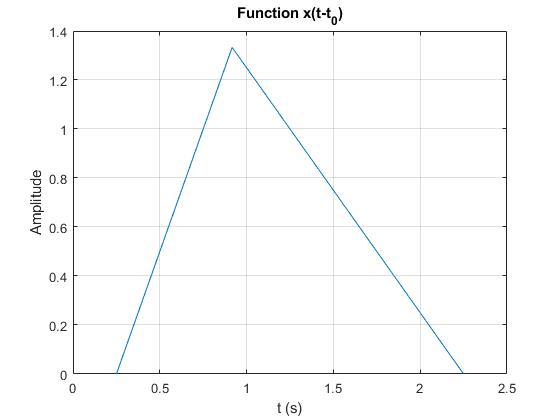

t0 = T/8;
figure
t=(0:Ts:T-Ts)+t0;
z = xFun(t-t0, T, Ts);
plot(t,z)
grid on
xlabel('t (s)')
ylabel('Amplitude')
title('Function x(t-t_0)')

z_n = analysis(z,t,T,N,Ts);

phaseShift = exp((-1i*2*pi*t0/T)*(-N:1:N));
plot(-N:N, 180*angle(phaseShift)/pi)
grid on
xlabel('Coefficient index (n)')
ylabel('Phse Shift (Degrees)')
plotFourierCoefficients(x_n,'x_n','x(t)',...
    z_n,'z_n','x(t-t_o)')

## Convolution in Time Domain

Assume that there are two function $x\left(t\right)$ and $y\left(t\right)$ with the same period, $T$, have Fourier coefficients $x_n$ and $y_n$, respectively. Let $z\left(t\right)$ be the periodic convolution of these two function, which is defined as.


$$\begin{array}{l}
z\left(t\right)\;=x\left(t\right)*y\left(t\right)\\
\;\;\;\;\;\;\;\;=\frac{1}{T}\int_0^T x\left(\tau \;\right)y\left(t-\tau \;\right)d\tau \;
\end{array}$$


The Fourier series of $z\left(t\right)$ is


$$\begin{array}{l}
\;\;\;z_n =\frac{1}{T}\int_0^T \left(\frac{1}{T}\int_0^T x\left(\tau \;\right)y\left(t-\tau \;\right)d\tau \right)e^{\left(\frac{-j2\pi \textrm{tn}}{T}\right)} \textrm{dt}\\
\;\;\;\;\;\;\;=\frac{1}{T}\int_0^T x\left(\tau \;\right)\frac{1}{T}\left(\int_0^T y\left(t-\tau \;\right)e^{\left(\frac{-j2\pi \textrm{tn}}{T}\right)} \textrm{dt}\right)d\tau 
\end{array}$$


Define $t\prime =t-\tau \;$, which we can also write as $t=t\prime +\tau \;$.


$$\begin{array}{l}
\;\;\;z_n =\frac{1}{T}\int_0^T x\left(\tau \;\right)\frac{1}{T}\left(\int_{-\tau \;}^{T-\tau \;} y\left(t\prime \;\right)e^{\left(\frac{-j2\pi \left(t\prime \;+\tau \;\right)n}{T}\right)} \textrm{dt}\prime \;\right)d\tau \\
\;\;\;\;\;\;=\frac{1}{T}\int_0^T x\left(\tau \;\right)e^{\left(\frac{-j2\pi \tau n}{T}\right)} \frac{1}{T}\left(\int_{-\tau \;}^{T-\tau \;} y\left(t\prime \;\right)e^{\left(\frac{-j2\pi t\prime n}{T}\right)} \textrm{dt}\prime \;\right)d\tau \\
\;\;\;\;\;\;=\frac{1}{T}\int_0^T x\left(\tau \;\right)e^{\left(\frac{-j2\pi \tau n}{T}\right)} y_{n\;} d\tau \\
\;\;\;\;\;\;=y_{n\;} \frac{1}{T}\int_0^T x\left(\tau \;\right)e^{\left(\frac{-j2\pi \tau n}{T}\right)} d\tau \\
{\;\;z}_n ={x_{n\;} y_n }_{\;} 
\end{array}$$


figure
t=0:Ts:T-Ts;
z = circularConvolution(x,y,Ts);
plot(t,z)
grid on
xlabel('t (s)')
ylabel('Amplitude')
title('Function z(t)=x(t)*y(t)')
z_n = analysis(z,t,T,N,Ts);

plotFourierCoefficients(x_n.*y_n,'x_n.y_n','x(t)*y(t)',...
    z_n,'z_n','z(t)')

## Convolution in Frequency Domain

Assume that there are two function $x\left(t\right)$ and $y\left(t\right)$ with the same period, $T$, have Fourier coefficients $x_n$ and $y_n$, respectively. Let $z\left(t\right)$ be the multiplication of these two function, which is defined as


$$z\left(t\right)\;=x\left(t\right)y\left(t\right)$$


The Fourier series of $z\left(t\right)$ is


$$\begin{array}{l}
\;\;\;z_n =\frac{1}{T}\int_0^T x\left(t\right)y\left(t\right)e^{\left(\frac{-j2\pi \mathrm{tn}}{T}\right)} \mathrm{dt}\\
\;\;\;\;\;\;\;=\frac{1}{T}\int_0^T \sum_{m=-\infty }^{\infty \;} x_m e^{\left(\frac{j2\pi \mathrm{mt}}{T}\right)} \sum_{k=-\infty \;}^{\infty \;} y_k e^{\left(\frac{j2\pi \mathrm{kt}}{T}\right)} e^{\left(\frac{-j2\pi \mathrm{tn}}{T}\right)} \mathrm{dt}\\
\;\;\;\;\;\;\;=\sum_{m=-\infty }^{\infty \;} x_m \sum_{k=-\infty \;}^{\infty \;} y_k \frac{1}{T}\int_0^T e^{\left(\frac{-j2\pi t\left(m+k-n\right)}{T}\right)} \mathrm{dt}\\
\;\;\;\;\;\;\;=\sum_{m=-\infty }^{\infty \;} x_m \sum_{k=-\infty \;}^{\infty \;} y_k \delta \left(m+k-n\right)\\
\;\;\;\;\;\;\;=\sum_{m=-\infty }^{\infty \;} x_m y_{n-m} \\
{\;\;\;z}_n =x_n *y_n 
\end{array}$$


figure
t=0:Ts:T-Ts;
z = x.*y;
plot(t,z)
grid on
xlabel('t (s)')
ylabel('Amplitude')
title('Function z(t)=x(t)*y(t)')
z_n = analysis(z,t,T,N,Ts);

z_n2 = conv(x_n,y_n);
z_n2 = z_n2(N+1:end-N);

plotFourierCoefficients(z_n2,'x_n*y_n','x(t)y(t)',...
    z_n,'z_n','z(t)')

## Complex Conjugate and Symmetry

Assume that there is a function $x\left(t\right)$ with the same period, $T$, have Fourier coefficients $x_n$. Let $z\left(t\right)$ be the complex conjugate of $x\left(t\right)$ defined as


$$z\left(t\right)\;=x^* \left(t\right)$$


The Fourier series of $z\left(t\right)$ is


$$\begin{array}{l}
\;\;\;z_n =\frac{1}{T}\int_0^T x^* \left(t\right)e^{\left(\frac{-j2\pi \mathrm{tn}}{T}\right)} \mathrm{dt}\\
\;\;\;\;\;\;\;={\left(\frac{1}{T}\int_0^T {\left(x^* \left(t\right)e^{\left(\frac{-j2\pi \mathrm{tn}}{T}\right)} \right)}^* \mathrm{dt}\right)}^* \\
\;\;\;\;\;\;\;={\left(\frac{1}{T}\int_0^T x\left(t\right)e^{\left(\frac{+j2\pi \mathrm{tn}}{T}\right)} \mathrm{dt}\right)}^* 
\end{array}$$


Define $m=-n$


$$\begin{array}{l}
\;\;\;z_n ={\left(\frac{1}{T}\int_0^T x\left(t\right)e^{\left(\frac{-j2\pi \mathrm{tm}}{T}\right)} \mathrm{dt}\right)}^* \\
\;\;\;\;\;\;={\left(x_m \right)}^* \\
\;\;z_n \;={x^* }_{-n} 
\end{array}$$


If $x\left(t\right)$ is a real signal, then 


$$\begin{array}{l}
x_n ={x^* }_{-n} \\
\textrm{real}\left(x_n \right)=\textrm{real}\left(x_{-n} \right)\\
\textrm{imag}\left(x_n \right)=-\textrm{imag}\left(x_{-n} \right)
\end{array}$$


which means the Fourier coefficents of a real values signal are conjugate symmetric. In other words, the real part of the Fourier coefficients are even symmetric while the imaginary parts of the Fourier coeficents are odd symmetric. 

Let's define a new complex x function.

x = x + 1i*y;
z = conj(x);

figure
x_n = analysis(x,t,T,N,Ts);
z_n = analysis(z,t,T,N,Ts);

plotFourierCoefficients(x_n,'x_n','x(t)',...
    z_n,'z_n','z(t)')

## Helper Functions

function c = analysis(f,t,T,N,Ts)
%analysis Fourier analysis

idx = 1;
c = zeros(1,2*N+1);
for n = -N:N
    expTerm = exp(-1i*2*pi*t*n/T);
    c(idx) = (Ts/T)*sum(f .* expTerm);
    idx = idx + 1;
end
end

function z = circularConvolution(x,y,Ts)
%circularConvolution Circular convolution

N = length(x);
T = N*Ts;
z = zeros(size(x));
tau = 0:length(x)-1;
for t=0:length(z)-1
    z(t +1) = (1/T)*sum(x(tau +1).*y(mod(t-tau,N) +1))*Ts;
end
end

function xq = xFun(t, T, Ts)
%xFun    Evaluate x function for t values

% Get x values for one period
[x,torig] = xValues(T, Ts);

% Find values of x for the given t where t < T (1 period)
tq = t(t<T);
xq1T = interp1(torig, x, tq);

% Replicate to match the whole t range
xqTemp = repmat(xq1T, 1, ceil(length(t) / length(xq1T)));
xq = xqTemp(1:length(t));
end

function [x,t] = xValues(T, Ts)
%xValues  Values of function x for one period

t = 0:Ts:T-Ts;
x = zeros(size(t));

% x = 2*t for 0<t<T/3
idx = t < T/3;
x(idx) = 2*t(idx);

% x = T-t for T/3<t<T
idx = (t >= T/3) & (t < T);
x(idx) = T - t(idx);
end

function [y,t] = yValues(T, Ts)
%xValues  Values of function y for one period

t = 0:Ts:T-Ts;
y = zeros(size(t));

% y = 2*t for 0<t<T/4
idx = t < T/4;
y(idx) = 2*t(idx);

% y = T for T/4<t<T/2
idx = (t >= T/4) & (t < T/2);
y(idx) = T/2;

% y = T + exp(-3(t+T/2)) for T/2<t<3T/4
idx = (t >= T/2) & (t < 3*T/4);
y(idx) = T/2 - 1 + exp(-3*(t(idx)-T/2));

% y = T + exp(-(t+T/2)) for 3T/4<t<T
idx = (t >= 3*T/4) & (t < T);
y(idx) = 0;
end

function plotFourierCoefficients(f1_n,coeffLabel1,funLabel1,...
    f2_n,coeffLabel2,funLabel2)

N = (length(f1_n)-1)/2;

figure
subplot(2,1,1)
stem(-N:N, real(f1_n))
hold on
stem(-N:N, imag(f1_n))
hold off
grid on
legend("real("+coeffLabel1+")", "imag("+coeffLabel1+")")
xlabel('Coefficient Index, n')
ylabel('Amplitude')
title("Fourier Coefficients for " + funLabel1)

subplot(2,1,2)
stem(-N:N, real(f2_n))
hold on
stem(-N:N, imag(f2_n))
hold off
grid on
legend("real("+coeffLabel2+")", "imag("+coeffLabel2+")")
xlabel('Coefficient Index, n')
ylabel('Amplitude')
title("Fourier Coefficients for " + funLabel2)
end